# Thresholding

binary and multiple

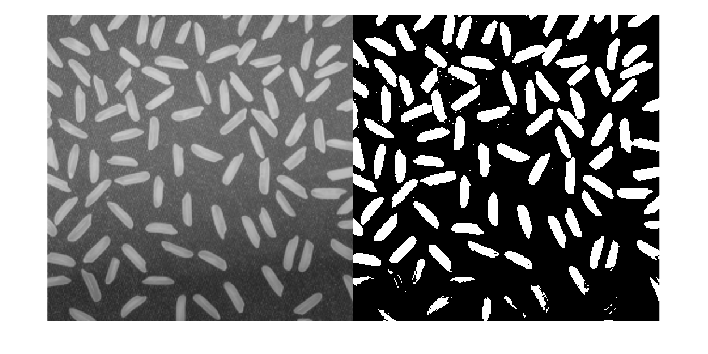

img = imread("rice.png");
BW = imbinarize(img);

montage({img, BW})


% Otsu's method
graythresh(img)

ans = 0.5137

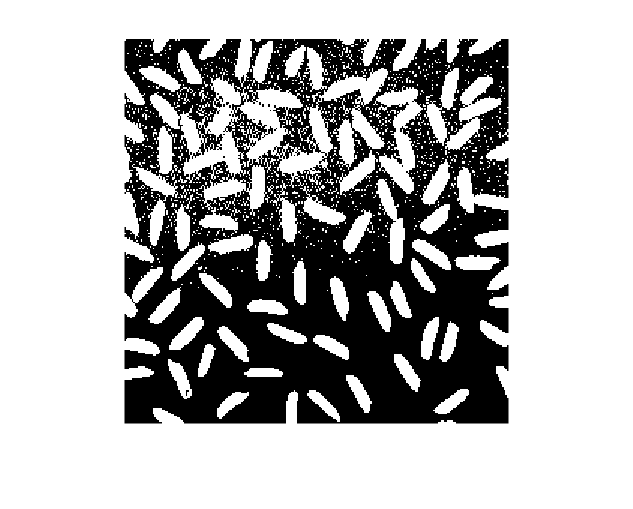

% Manual Thresholding
BW2 = imbinarize(img, 0.44);
imshow(BW2)

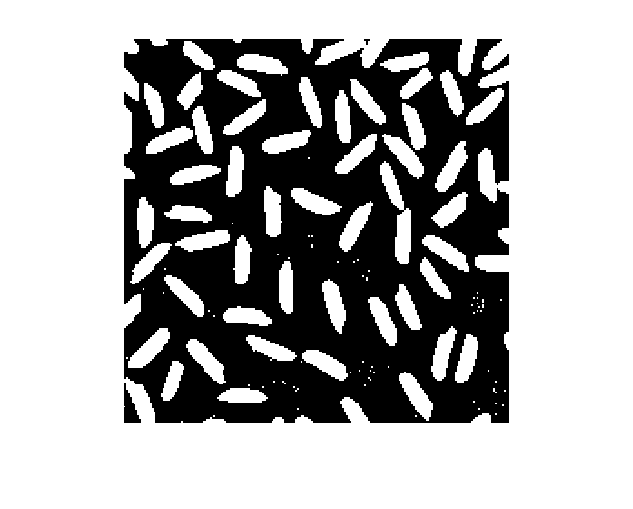

BW3 = imbinarize(img, "adaptive");
imshow(BW3)

img = imread("00140.jpg");
graythresh(img) * 255

ans = 103

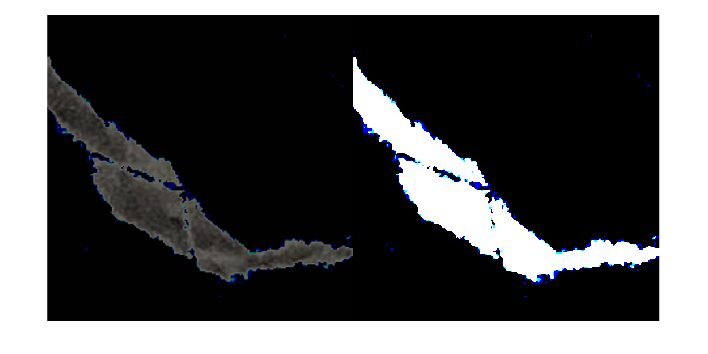

BW = imbinarize(img);

maskedImg = img;
maskedImg(BW) = 1;

montage({maskedImg, ~BW})

## Multi Thresholding

img = imread("armxray.png");
thresValues = multithresh(img, 3)

thresValues = 1×3 uint8 row vector
    54   147   223



BW = imquantize(img, thresValues);
% number of non zero matrix elements

fracture = BW == 4;
nnz(fracture)

ans = 172544

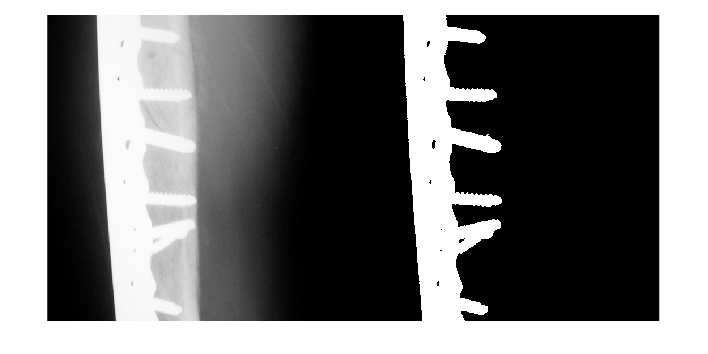

montage({img, fracture})